% downsampling & upsampling 
clear; clc; close all
fp = fopen('../audio/test_mono.wav','rb');

% Spectrum parameters setup
window = 512; 
noverlap = 120; % Number of overlapping samples per segment
nfft = 320; % Length of FFT transformation

figure(1)
x = fread(fp,'short'); disp(length(x))

      240039



Fs = 16000; 
subplot(3,1,1); plot(x); 
xlabel('time in samples'); axis('tight')
title('audio sampled at 16kHz') 

% upsampling 
% y = interp(x,4);
y = my_up(x,4); 

      960156



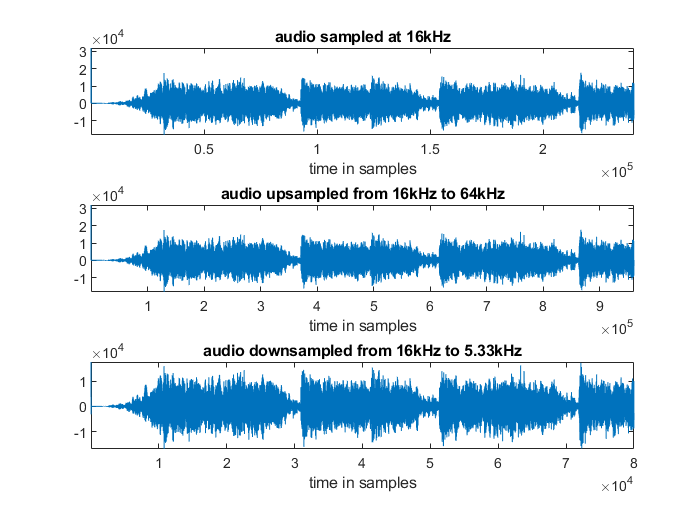

subplot(3,1,2); plot(y); axis('tight')
xlabel('time in samples') 
title('audio upsampled from 16kHz to 64kHz'); 

% downsampling 
z = decimate(x,3); 
subplot(3,1,3); plot(z); axis('tight')
xlabel('time in samples') 
title('audio downsampled from 16kHz to 5.33kHz'); 

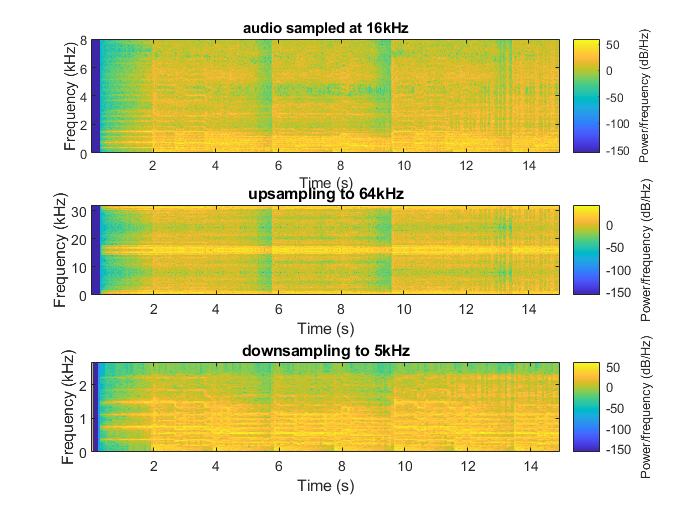


figure(2)
subplot(3,1,1); spectrogram(x,window,noverlap,nfft,Fs,'yaxis'); 
title('audio sampled at 16kHz'); 
subplot(3,1,2); spectrogram(y,window,noverlap,nfft,Fs*4,'yaxis'); 
title('upsampling to 64kHz'); 
subplot(3,1,3); spectrogram(z,window,noverlap,nfft,Fs/3,'yaxis'); 
title('downsampling to 5kHz'); 

function out = my_up(x,n)
    y = zeros(length(x)*n,1);

    for g = 0 : length(x) - 1
        y(1+n*g) = x(g+1);
    end
    disp(length(y))
    scope = linspace(0,length(y));
    out = conv(sinc(scope),y);
end

function out = my_down(x,n)
    f = 1; g = 1;
    y = zeros(length(x)/n, 1);
    while f <= length(x) / n
        y(f) = x(g);
        g = g + n;
        f = f + 1;
    end
end